% change directory in order for relative references to work
cd(fileparts(matlab.desktop.editor.getActiveFilename))

# Deep learning

## Working with images

Image classification can be done with convolutional neural networks (CNN). Before going into detail let's go over some basics and illustrate some concepts. You are familiar with the concept of convolution from the course on signals:

$(f*g)(t)=\int _{-\infty }^{\infty }f(\tau )g(t-\tau )\,d\tau \;\text{(continuous)}$ or $(f*g)[n]=\sum _{m=-\infty }^{\infty }f[m]g[n-m] \ \text{(discrete)}$

In the above expressions the function $g(t)$ can be seen a filter being applied to $f(t)$. The weights of a CNN correspond with the properties of the filters that are being used. Given enough data you will be able to find the optimal values of these filters by training the network (i.e. the filters are learned from the data). 

The application of a filter on data leads to what is called a feature map.

### convolution (1D)

The definition of a convolution of a vector $u \in \mathbb{R}^{m\times1}$ and a vector $v \in \mathbb{R}^{n\times1}$ is given by:


$$w(k) = \sum_j u(j)v(k-j+1)\text{ where } j= \max \{1, k+1-n\}:1:\min \{ k,m\}$$


There are different ways of applying the filter to the input sequence. This will change the shape of the resulting feature map. A one dimensional example is shown below

u = [3 0 0 1 1 0 0 1 1 10]; % data
v = [0 2 1];                % filter

% w(1):
% j = 1:1:1
% => w(1) = u(1)*v(1) = 0
% w(2):
% j = 1:1:2
% => w(2) = u(1)*v(2)+u(2)*v(1) = 6
% w(11):
% j = 9:1:10
% => w(11) = u(9)*v(3) + u(10)*v(2) = 21

conv(u,v) % total convolution (m + n - 1)

ans =      0     6     3     0     2     3     1     0     2     3    21    10


conv(u,v,'same') % same output size

ans =      6     3     0     2     3     1     0     2     3    21


conv(u,v,'valid')

ans =      3     0     2     3     1     0     2     3


The option "valid" is selected this means that the convolution will only be done for the locations in our data where the filter actually fits.

### convolution (2D)

The definition of a convolution of a matrix $A$ and a matrix $B$ is given by:

$C(j,k) = \sum_p\sum_qA(p,q)B(j-p+1,k-q+1)$ , where $p$ and $q$ run over all values that lead to legal subscripts of $A(p,q)$ and $B(j-p+1,k-q+1)$.

The result of convolving the data with our filter is shown below. 

d = [1 1 1 0 0;
     0 1 1 1 0;
     0 0 1 1 1;
     0 0 1 1 0;
     0 1 1 0 0];
f = [1 1 1;
     0 0 1;
     0 0 1];
C = conv2(d,f)

C =      1     2     3     2     1     0     0
     0     1     3     4     3     1     0
     0     0     2     4     5     3     1
     0     0     1     3     4     3     1
     0     1     2     2     3     2     1
     0     0     0     1     2     1     0
     0     0     0     1     1     0     0


conv2(d,f,"valid")

ans =      2     4     5
     1     3     4
     2     2     3


### Illustrations

Let's illustrate the affect of a couple of filters on an image. Note that a standard color image has 3 channels, one for red, blue and green. For this application we flatten the channels into one by averageing the values.

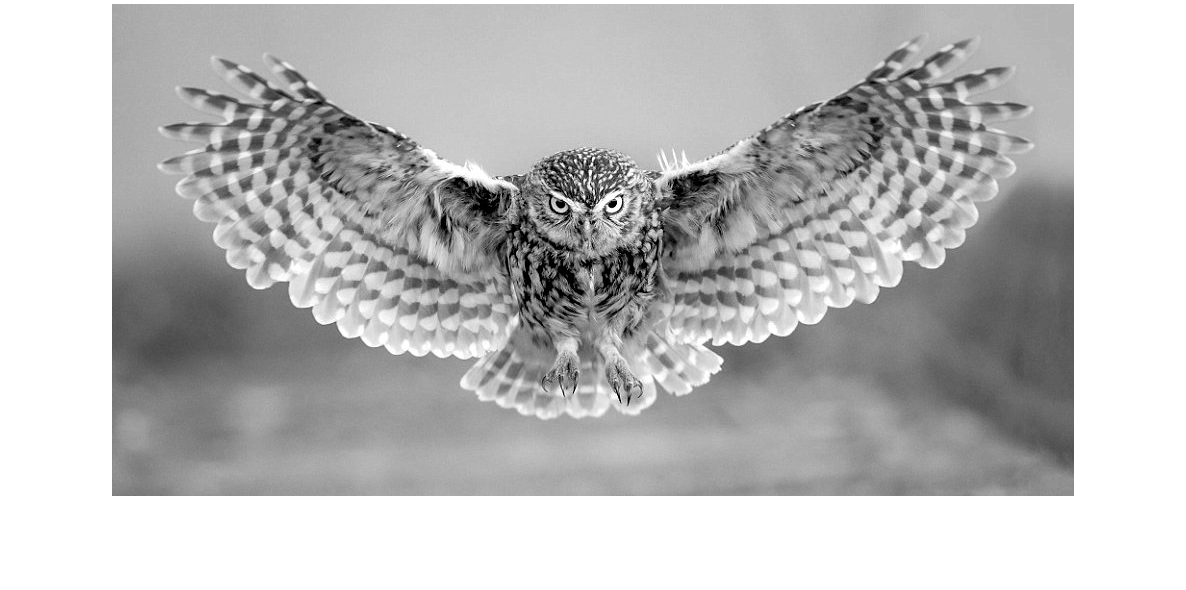

% Load single image as matrix
I = mean(imread("img/owl.jpg"),3);
figure
imshow(I,[0, 255])

% effect of a set of simple filters on the image:
f = {[1 1;0 0], ...
     [0 0;1 1], ...
     [0 1 1; 0 1 0], ...
     [1 0 0; 0 1 0; 0 0 1], ...
     [1/2 1 1/2;1/2 1 1/2;1 0 1],...
     [3 -1 0; 3 -2 0],...
     [1 1 -1 -1; 1 1 -1 -1;1 1 -1 -1;1 1 -1 -1],...
     [1 1 -1 -1; -1 -1 1 1;1 1 -1 -1;-1 -1 1 1]};
figure('Position', [0 0 900 600])
psize = ceil(sqrt(length(f)));
for i = 1:length(f)
    subplot(psize,psize,i)
    res = conv2(I, f{i},"same");
    imshow(res,[0, 255])
    title(sprintf("filter %i ( %i x %i px)",i,size(res,1), size(res,2)))
end

### CNN in practice

By now you know that applying the filter to the entire inpute array will result in a two-dimensional arary of outputs called the feature map. In general, this feature map will be passed along to a nonlinearity (e.g. ReLU). We might even use multiple convolution layers in a single model. In addition to the already mentioned layer types, you can also include a pooling layer. This type of layer combines the outputs of clusters of neurons into a single neuron in the next layer.

In pratice, CNNs will use multiple filters (for a given convolution layer) and may even use multiple convolution layers. In addition to the convolution layers, you might also encounter ReLU layers, pooling layers and fully connected layers.

- Convolutional layers apply a convolution operation to the input. This passes the information on to the next layer.

- Pooling combines the outputs of clusters of neurons into a single neuron in the next layer.

- Fully connected layers connect every neuron in one layer to every neuron in the next layer.

Other jargon that you might come across:

- filter size: size of the filter you are using (3x3 or 5x5 is common when dealing with images)

- stride: Step size for traversing the input vertically and horizontally

- dilation factor: space between the elements of the filter. The dilation factor determines the step size for sampling the input or equivalently the upsampling factor of the filter.  For a classical filter, this value is equal to one.

- padding: add rows or columns of zeros to the borders of an image input. This allows you to control the size of the feature map.

The number of weights in a filter is equal to width x height x number of channels. The number of filters will determine the number of channels we have in the output of the convolution layer.

The total number of parameters in a convolution layer will be equal to (filter_width x filter_height x number of channels in the image + 1) x number of filters. Below you can see an illustration of a 3x3 filter applied on a 5x5 image using a paading of one, a dilation factor of one and a stride of one.

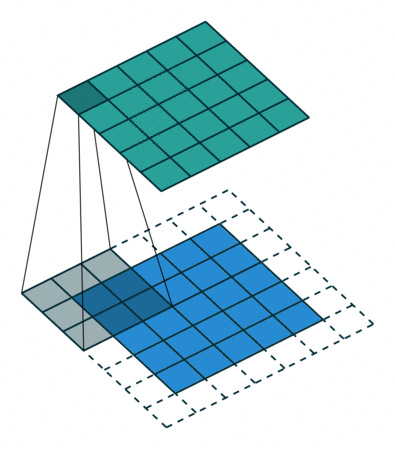

The difference between a convolution layer and a fully connected layer can be described as follows: In a convolutional layer neurons only receive input from a subarea of the previous layer. In a fully connected layer each neuron receives input from *every* element of the previous layer. The image below gives you an overview of the process (source).

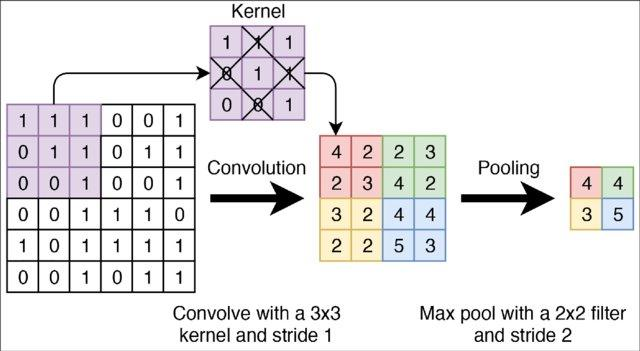

### Application 1 - Revisiting the handwritten number recognition again

% Load up the data
D = readtable('./datasets/MNIST-train.csv');
% use only 10% of data for training
part = cvpartition(D.label,"HoldOut", 0.9, "Stratify", true);
% limit data for training
d = D(part.training,:);
% data for testing (limit to 1k entries)
t = D(part.test,:);
t = t(1:1000,:);

We will be using the same data as before, however, we will need to make some modifications to how the data is represented. Up to now, we just used the information of the pixels, without taking into account the information on neigbouring pixels. We will reshape the data in tabular form into a (28, 28, 1, 4200) sized tensor. The first two values are the image size, the third value is the number of channels in our image (only one as it is a grayscale image). The value 4200 is the number of training examples. For larger volumes of data (that don't necessarily fit in memory), you should use a datastore.

% important to know that Matlab is column major, hence the transpose
X_train = reshape(d{:,2:end}', 28,28, 1, []);
Y = d{:,1}; % contains the actual number
Y_train = categorical(Y); % contains the category
X_val = reshape(t{:,2:end}', 28,28, 1, []);
Y_val = categorical(t{:,1});

% Quick reference to verify transformation worked as intended
figure()
for i = 1:16
    subplot(4,4,i)
    imshow(X_train(:,:,1,i)');  
    title(sprintf('%i', Y(i))) 
end

Now that we have our data in an proper format, all we need to do is build and train the network. Note that you can also use the Deep Network Designer toolbox to assist you with this.

layers = [
    % input layer (single channel)
    imageInputLayer([28 28 1],"Name","Grayscale input")
    % convolution layer, 16 filters of size 3x3 filter size
    convolution2dLayer(3,16,"Name","conv_1_3x3")
    % normalize a mini-batch of data across all observations for each channel independently
    batchNormalizationLayer
    % REctified Linear Unit (ReLU) layer
    reluLayer("Name","relu_1")
    % pooling layer
    maxPooling2dLayer(2,"Name","maxpool_1","Stride",2)
    % another convolution layer, 32 filters of size 3x3 filter size
    convolution2dLayer(3,32,"Name","conv_2_3x3")
    % normalize a mini-batch of data across all observations for each channel independently
    batchNormalizationLayer
    % another ReLU layer
    reluLayer("Name","relu_2")
    % another pooling layer
    maxPooling2dLayer(2,"Name","maxpool_2","Stride",2)
    % fully connected
    fullyConnectedLayer(10,"Name","fc")
    % classification part
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

option = trainingOptions('adam',"Plots","none","MiniBatchSize",128,...
    "Shuffle","every-epoch", "ValidationData",{X_val, Y_val},"Verbose",false);
[net, info] = trainNetwork(X_train,Y_train, layers, option);

% overview of our network
analyzeNetwork(net)

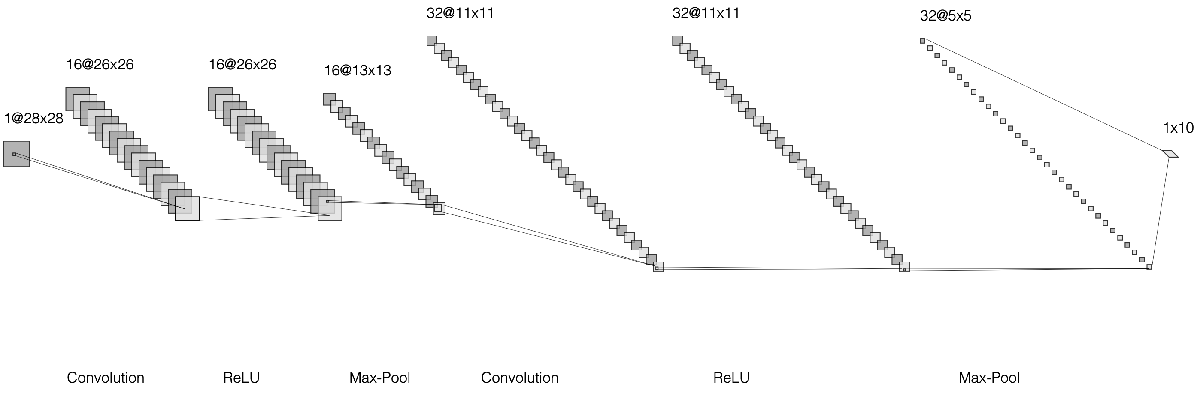

% Small illustration
figure("Position",[0 0 600 200])
plot(info.ValidationAccuracy(~isnan(info.ValidationAccuracy)),'-o');
xlabel('Validation step');
ylabel("Validation accuracy");
title(sprintf("Accuracy evolution (final accuracy of %1.2f%%)", info.ValidationAccuracy(end)));

#### Understanding and interpreting the results

We have trained a model that performs reasonably well. in order to better understand its inner workings, we will look into the effect of the filters by analyzing the results of each layer.

% overview of the layers
net.Layers

ans =   12×1 Layer array with layers:

     1   'Grayscale input'   Image Input             28×28×1 images with 'zerocenter' normalization
     2   'conv_1_3x3'        Convolution             16 3×3×1 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'batchnorm_1'       Batch Normalization     Batch normalization with 16 channels
     4   'relu_1'            ReLU                    ReLU
     5   'maxpool_1'         Max Pooling             2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv_2_3x3'        Convolution             32 3×3×16 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'batchnorm_2'       Batch Normalization     Batch normalization with 32 channels
     8   'relu_2'            ReLU                    ReLU
     9   'maxpool_2'         Max Pooling             2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    10   'fc'          

% select a specific image
n = 5; % img number
img = X_train(:,:,:,n);
actual_label = Y(n);
% run it through the network
conv1_res = activations(net,img,'conv_1_3x3'); % 26x26x16 size => why?
conv2_res = activations(net,img,'conv_2_3x3'); % 11x11x32 size => why?
% resize for plotting
sz1 = size(conv1_res);
conv1_res = reshape(conv1_res,[sz1(1) sz1(2) 1 sz1(3)]);
sz2 = size(conv2_res);
conv2_res = reshape(conv2_res,[sz2(1) sz2(2) 1 sz2(3)]);
% normalize for plotting (map to [0,1]
conv1_res = (conv1_res - min(min(min(conv1_res)))) / (max(max(max(conv1_res))) - min(min(min(conv1_res))));
conv2_res = (conv2_res - min(min(min(conv2_res)))) / (max(max(max(conv2_res))) - min(min(min(conv2_res))));
% actual plot
figure("Position",[0 0 1000 400])
subplot(1,3,1)
I1 = imtile(conv1_res,'GridSize',[4 4],'ThumbnailSize', [100 100]);
imshow(I1);
title(sprintf("conv\\_1, actual label = %i", actual_label))
subplot(1,3,2:3)
I2 = imtile(conv2_res,'GridSize',[4 8],'ThumbnailSize', [80 80]);
imshow(I2)
title(sprintf("conv\\_2, actual label = %i", actual_label))

### Task - Improving handwritten number recognition

Now that you have seen an implementation of a CNN for handwriting recognition, try to build a better one for yourself. You can use a form of optimisation similar to what you did in previous sessions. You could experiment with the setting of the differennt filters. 

## Working with text

clear; close all force; clc

Computational linguistics and natural language processing (NLP) have profited from the advances in neural networks as well. In what follows we will see some application of working with text using neural networks. Most methods use a form of word or sentence embedding to achieve this. If you want to work with "classical" machine learning algorithms, you will most likely use another representation such as a bag-of-words model or a TF-IDF representation.  In particular, we will be using the [GloVe](https://nlp.stanford.edu/projects/glove/) embeddings (the original paper is available on the site if you want more details).

The application we will be working on is a binary classification problem based on social media data. We want to be able to classify a tweet as being related to misinformation or trusted news articles. For this small project, we will encounter additional challenges that we did not encounter before such as the need of preprocessing our data before we can use it.

Note: 

- this requires the Text Analysis toolbox.

- obtaining the original data from the web has to be done outside of Matlab.

% load up existing embedding (download from BelADL)
filename = "./datasets/glove.twitter.27B.25d.txt";
emb = readWordEmbedding(filename);

It possible to classify text using a CNN, to do so, we need to transform the text into an image:

- All documents need to be the same size,so you need to pad or truncate the observations to have constant length *S*. We will determine a good value for S later on. By default Matlab uses the longest sequence length, but if you have a long tail in the length distribution, this might lead to unnecessary memory usage.

- Each document needs to be converted into a sequence of word vectors of length *C* using a word embedding (25 dimensions in our case). 

These operations allow us to represent any document as a 1-by-*S*-by-*C* image (an image with height 1, width *S*, and *C* channels).

#### Text preprocessing

You could use the raw text, but this might not work as well as you hope. We will preprocess the raw text. This includes techniques such as extracting individual words or multiword phrases (n-grams), convert text into numerical representations, remove uppercase (e.g. "Dog" and "dog" should be the same word), identify specifics etc. The preprocessing is done in a function and an illustration is shown below.

str = 'BREAKING: The flowers may bloom in #May @flowerpot more info on https://www.flowers.com/ :D :-)';
% setup replacement patterns using regex
patterns = ["#\w*" "<hashtag>";
            "@\w*" "<user>";
            "http[s]?://(?:[a-zA-Z]|[0-9]|[$-_@.&+]|[!*\(\),]|(?:%[0-9a-fA-F][0-9a-fA-F]))+" "<url>"];
% preprocessing demo
preprocessdemo(str, patterns, emb, 15);

The actual preprocessing function will make use parse all the data in a single pass and reshape it into a datastore that we can use to train our model(s). In practice we also separate the actual text preprocessing and the embedding phase. Why would we want do this?

#### Fetching the data

Note that this for this application, we use a datastore instead of loading everything into memory. For real life applications, it is often the case that the data does not even fit in memory. This will allow you to familiarise yourself with this way of working.

% Connect with the data
fn_train = "./datasets/text_data_train.csv";
fn_val = "./datasets/text_data_val.csv";
tn = "Text"; ln = "Label";
% generate a datastore, specifying the variables we want and the delimiter used
train_data = tabularTextDatastore(fn_train,'SelectedVariableNames',[tn ln],'Delimiter',' |||| ', 'TextType',"string");
val_data = tabularTextDatastore(fn_train,'SelectedVariableNames',[tn ln],'Delimiter',' |||| ', 'TextType',"string");
preview(train_data)

raw text            : BREAKING: The flowers may bloom in #May @flowerpot more info on https://www.flowers.com/ :D :-)
replaced pattern 1  : BREAKING: The flowers may bloom in <hashtag> @flowerpot more info on https://www.flowers.com/ :D :-)
replaced pattern 2  : BREAKING: The flowers may bloom in <hashtag> <user> more info on https://www.flowers.com/ :D :-)
replaced pattern 3  : BREAKING: The flowers may bloom in <hashtag> <user> more info on <url> :D :-)
tokenized           : BREAKING | : | The | flowers | may | bloom | in | <hashtag> | <user> | more | info | on | <url> | :D | :-)
lowercase           : breaking | : | the | flowers | may | bloom | in | <hashtag> | <user> | more | info | on | <url> | :d | :-)
embedded            : cell {25x15x1 single}
embedded, reshaped  : cell {1x15x25 single}


% acquire the labels for training
labels = readLabels(train_data,ln);
% determine the amount of classes
classNames = unique(labels);
% determine the amount of training examples
numObservations = numel(labels);
% sanity checks and data distrubution:
nvalid = length(find( arrayfun(@(RIDX) strcmp(labels{RIDX,1}, 'valid'), 1:size(labels,1)) ));
nfake = length(find( arrayfun(@(RIDX) strcmp(labels{RIDX,1}, 'fake'), 1:size(labels,1)) ));
assert(nvalid + nfake == length(labels),"something might be wrong with the data")

#### Document length

The raw data is now available. Before doing the actual embedding, let's look at the distribution of the document length and get an idea of an appropriate value

% preprocess data and get an idea of the document length distribution
doc_lengths = transform(train_data, @(x) doclength(trfText(x,'patterns',patterns, 'embedding',emb,'sequenceLength', 20,...

ans = 8×2 table
                                                                                                                                            Text                                                                                                                                              Label 
    _____________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________    _______

    "Project Veritas - Google Exec Decries Trump's Election: 'How Do We Prevent It from Happening Again' | Breitbart https://t.co/4zphilSQpr"                                                                                                                                                "fake" 
    "California judge blocks law req

                                                       'classNames',classNames,'preprocessonly', true)));
figure()
% percentage of the documents that needs to be covered by our method
lim = 99;
cutoff = quantile(readall(doc_lengths), lim/100);
histogram(readall(doc_lengths), 'Normalization',"pdf");
xlabel("document length");
ylabel("bin probability");
title(sprintf("document length distribution (%i%% cutoff: %i)",lim,cutoff));
xlim([0,100])
set(gca,'YScale','log')

You can get an idea of a good document length. We will use this cutoff value for the rest of the process.

#### Data embedding

% make use of the document embeddings
embedded_data_train = transform(train_data, @(x) trfText(x, 'patterns',patterns, 'embedding',emb,'sequenceLength', cutoff, 'classNames',classNames));
embedded_data_val = transform(val_data, @(x) trfText(x, 'patterns',patterns, 'embedding',emb,'sequenceLength', cutoff, 'classNames',classNames));
preview(embedded_data_train)

#### Building the model

Everything is known, so we can now build and evaluate our CNN model

% get input size
inputSize = [1 cutoff emb.Dimension;];
% settings
ngramLengths = [2 3 4 5];
numBlocks = numel(ngramLengths);
numClasses = numel(classNames);
% set number of filters
numFilters = 200;

%% actual CNN layout

% input layer
layer = imageInputLayer(inputSize,'Normalization','none','Name','input');
lgraph = layerGraph(layer);
% convolution blocks for n-grams
for j = 1:numBlocks
    N = ngramLengths(j);
    

ans = 8×2 table
       Predictors       Responses
    ________________    _________

    {1×58×25 single}      fake   
    {1×58×25 single}      valid  
    {1×58×25 single}      fake   
    {1×58×25 single}      fake   
    {1×58×25 single}      fake   
    {1×58×25 single}      fake   
    {1×58×25 single}      valid  
    {1×58×25 single}      valid  


    block = [
        convolution2dLayer([1 N],numFilters,'Name',"conv"+N,'Padding','same')
        batchNormalizationLayer('Name',"bn"+N)
        reluLayer('Name',"relu"+N)
        dropoutLayer(0.2,'Name',"drop"+N)
        maxPooling2dLayer([1 cutoff],'Name',"max"+N)];
    
    lgraph = addLayers(lgraph,block);
    lgraph = connectLayers(lgraph,'input',"conv"+N);
end
% concatenation layer for combining the n-gram blocks
layers = [
    depthConcatenationLayer(numBlocks,'Name','depth')
    fullyConnectedLayer(numClasses,'Name','fc')
    softmaxLayer('Name','soft')
    classificationLayer('Name','classification')];
% connect the concatenation layer with the blocks
lgraph = addLayers(lgraph,layers);
for j = 1:numBlocks
    N = ngramLengths(j);
    lgraph = connectLayers(lgraph,"max"+N,"depth/in"+j);
end

figure
plot(lgraph)
title("Network Architecture")
% some training options
miniBatchSize = 128;
numIterationsPerEpoch = floor(numObservations/miniBatchSize);


options = trainingOptions('adam', ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','never', ... % you can't shuffle a datastore (read sequentially from disk)
    'Plots','training-progress', ...
    'MaxEpochs',3,...
    'Verbose',false,...
    'ValidationData',embedded_data_val,...
    'ValidationFrequency', 200,...
    'ExecutionEnvironment', 'CPU',...
    'CheckpointPath','./trained_nets/'); % This last option will store intermediate checkpoints

% actual training of the network
[net, info] = trainNetwork(embedded_data_train,lgraph,options);

info.FinalValidationAccuracy

If you want to resume training later on you can do this as shown below:

load('./data/net_checkpoint__693__2022_02_21__17_48_36.mat','net')

options = trainingOptions('adam', ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','never', ... % you can't shuffle a datastore (read sequentially from disk)
    'Plots','training-progress', ...
    'MaxEpochs',3,...
    'Verbose',false,...
    'ValidationData',embedded_data_val,...
    'ValidationFrequency', 200,...
    'ExecutionEnvironment', 'CPU',... % train on single CPU cores 
    'CheckpointPath','./data/'); % This last option will store intermediate checkpoints
[net2, info2] = trainNetwork(embedded_data_train, layerGraph(net),options);

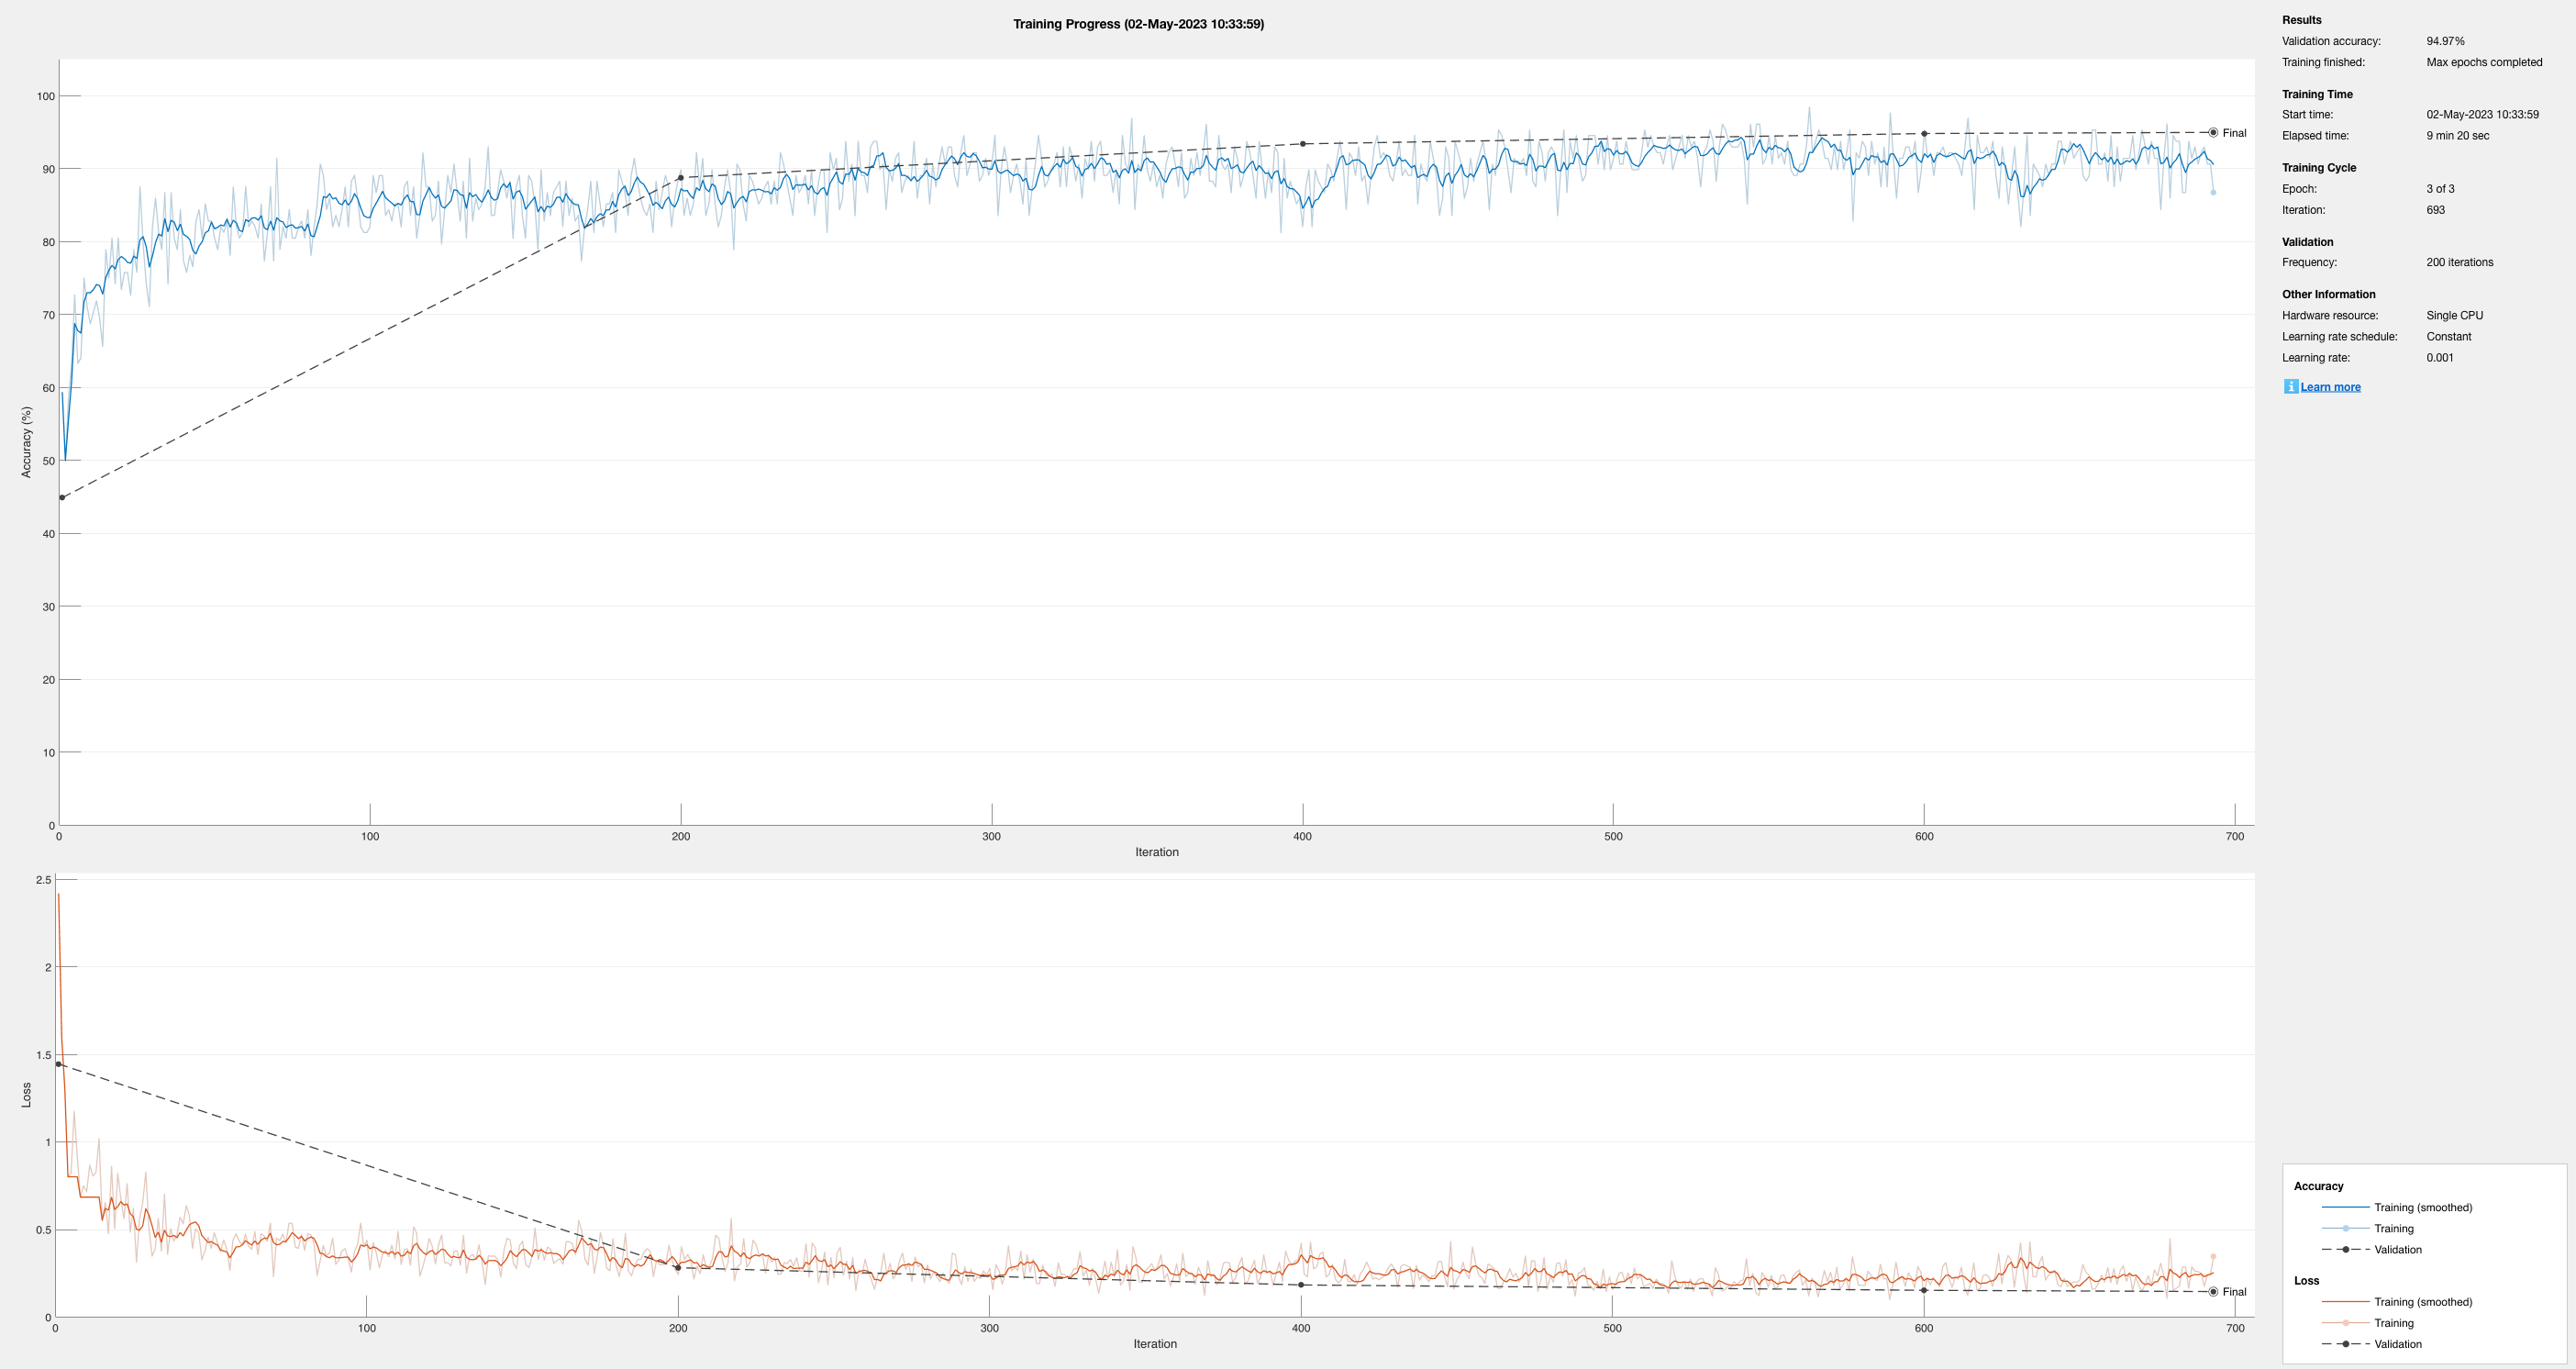

function trf = trfText(data, NameValueArgs)

    % trfText Transfrom text data store into an embedding
    % 

ans = 94.9675

    % use 'preprocessonly' = true to stop after preprocessing
    arguments
        data
        NameValueArgs.patterns
        NameValueArgs.embedding
        NameValueArgs.sequenceLength
        NameValueArgs.classNames
        NameValueArgs.preprocessonly = false
    end

    % Extract the text
    textData = data{:,1};
    % Extract the labels
    labels = data{:,2};
    
    % Prepocess text
    trf = preprocessText(textData,NameValueArgs.patterns);
    if NameValueArgs.preprocessonly
        return
    end
    %fprintf('class of trf: %s\n',class(trf));
    
    % Embed text
    trf = embedText(trf, NameValueArgs.embedding, NameValueArgs.sequenceLength);
    
    % transform to table
    tbl = table;
    tbl.Predictors = trf;
    
%    fprintf('cateforical valueset: %s\n',NameValueArgs.classNames{});
    responses = categorical(labels,NameValueArgs.classNames);
    
    % add labels to table
    tbl.Responses = responses;
    
    trf = tbl;
end

function docs = preprocessText(textData, patterns)
    % preprocessText prepare text data for deep learning
    % 
    % docs = preprocessText(textData, patterns)
    % returns a table after having done the preprocessing.
    %
    % arguments:
    % - textdata: data you want to transform
    % - pattern: a cell containing a regular expression pattern in the
    % first column and the replacement tag in the second
    
    res = textData;
    % replace regex patterns (cf. how GloVe was constructed, not complete, only as illustration)
    for i = 1:size(patterns, 1)
        pattern = patterns{i,1};
        replace = patterns{i,2};
        res = regexprep(res,pattern,replace);
    end
    % tokenize the document (using own tags)
    res = tokenizedDocument(res,'CustomTokens',string(patterns(:,2))', 'Language',"en");
    % lowercase everything
    docs = lower(res);
end

function embs = embedText(docs, embedding, sequenceLength)
    % embedText transform tokenized documents into 1-by-S-by-C image
    % 
    % embs = embedText(docs, embedding, sequenceLength) returns embedding
    %
    % arguments:
    % - docs: collections of tokenized documents
    % - embedding: an existing embedding
    % - sequenceLength : length used for each document
    
    % embedding itself
    embs = doc2sequence(embedding,docs,'Length',sequenceLength);
    % reshaping
    embs = cellfun(@(X) permute(X,[3 2 1]),embs,'UniformOutput',false);
    
end

function labels = readLabels(ttds,labelName)
    % make copy for separate use (no data is copied, only the reference)
    ttdsNew = copy(ttds);
    % use only the labelname (i.e. subset of the data)
    ttdsNew.SelectedVariableNames = labelName;
    % read the entire datastore as a table
    tbl = readall(ttdsNew);
    % return selected column only
    labels = tbl.(labelName);
end

function res = preprocessdemo(textData, patterns, embedding, sequenceLength)
    res = textData;
    fprintf('%-20s: %s\n','raw text', res);
    % replace regex patterns (cf. how GloVe was constructed, not complete, only as illustration)
    for i = 1:size(patterns, 1)
        pattern = patterns{i,1};
        replace = patterns{i,2};
        res = regexprep(res,pattern,replace);
        fprintf('%-20s: %s\n',sprintf('replaced pattern %i', i), res);
    end
    % tokenize the document (using own tags)
    res = tokenizedDocument(res,'CustomTokens',string(patterns(:,2))');
    fprintf('%-20s: %s\n','tokenized',join(res.tokenDetails.Token,' | '));
    % lowercase everything
    res = lower(res);
    fprintf('%-20s: %s\n','lowercase',join(res.tokenDetails.Token,' | '));
    
    % Convert document to embeddingDimension-by-sequenceLength-by-1 image
    res = doc2sequence(embedding,res,'Length',sequenceLength);
    fprintf('%-20s: %s {%ix%ix%i single}\n','embedded',class(res),size(res{1,1},1),size(res{1,1},2),size(res{1,1},3));
    
    % Reshape images to be of size 1-by-sequenceLength-embeddingDimension.
    res = cellfun(@(X) permute(X,[3 2 1]),res,'UniformOutput',false);
    fprintf('%-20s: %s {%ix%ix%i single}\n','embedded, reshaped',class(res),size(res{1,1},1),size(res{1,1},2),size(res{1,1},3));
end

